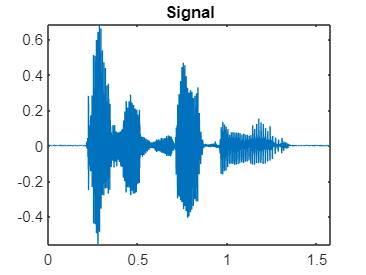

clc;
close all;
clear all;

[s0,Fs] = audioread('a0030.wav');
s = s0(:,1);
s1 = s0(:,2);

t = 1/Fs:1/Fs:size(s,1)/Fs;

plot(t,s);
title("Signal")

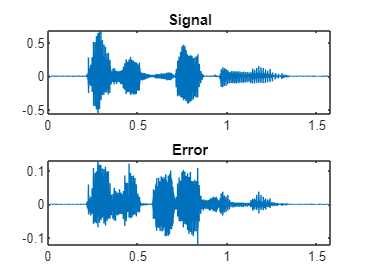


a = lpc(s,8);

siglen = length(s);

predicted = filter([0,-a(2 : end)],1,s);

e = s-predicted;

subplot(2,1,1)
plot(t,s);
title("Signal")
subplot(2,1,2)
% plot(t,predicted);
% title("Predicted")
% subplot(3,1,3)
plot(t,e);
title("Error")

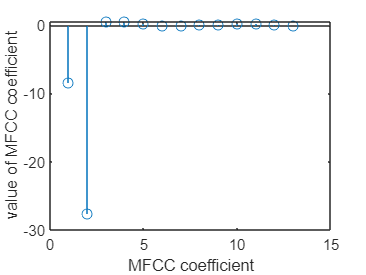

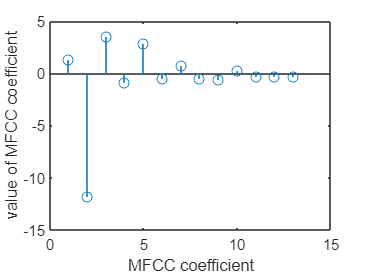

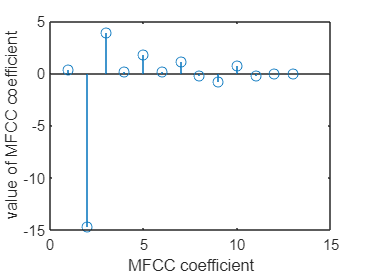

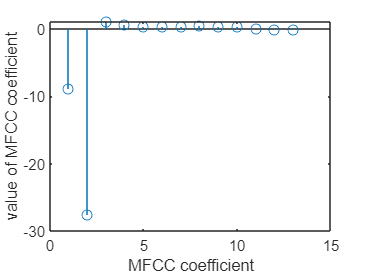


figure

coeffs = mfcc(s,Fs);

val = size(coeffs,1);

coeff = coeffs(:,1:13);

for i = 1 : 50 : val
    stem(coeff(i,1:13));
    xlabel('MFCC coefficient');
    ylabel('value of MFCC coefficient');
    figure;
end